# Sample and plot scaling data

This reproduces the figures in the paper and SI. We exported some of the results to python for nicer visualisation. Requires the optimisation and statistics/machine learning toolboxes. You will also need to place the scripts subtightplot.m and tightfig.m in the same folder as this script (or on your matlab path). They have been bundled here for ease of review purposes only.

This is not computationally intensive memory wise, but to run all bootstraps from scratch may take an hour or more on a laptop. The lower end of time estimates were done on a 13" 2018 macbook pro (2.5Ghz, 16GB RAM). Pre-computed results are therefore provided to save time, but it's possible to uncomment and run the bootstraps if desired. 

Colourblind friendly palette from Paul Tol: https://personal.sron.nl/~pault/

### Load the data

Load the data and create laminar/turbulent subtables to make methods easier to follow. 

% suggest clearing variables but left commented as default
% clear

load('scalingDataTables_forreview.mat')  % load the raw data tables

% % Remove any corrupt entries from encoding issues (shouldn't be any from
% % the .mat file, but uncomment if necessary)
% scalingdata( any(ismissing(scalingdata),2), :) = [];  % raw and turb adjusted data
% fishingadj( any(ismissing(fishingadj),2), :) = []; % fishing adjusted data


% here we have used 10cm as the border between laminar-turbulent but you
% can change to 8cm (the empirically determined structural break) with
% negligible effect on the results. 1-10cm is a transition zone - whether
% the regime boundary falls on the upper or lower threshhold varies between
% studies.

% Laminar regime organisms
laminartable = scalingdata(scalingdata.size < 0.1, :);
% Turbulent regime organisms
turbulenttable = scalingdata(scalingdata.size >= 0.1, :);

% Laminar regime organisms (manually curated data only)
laminartableman = scalingdataman(scalingdataman.size < 0.1, :);
% Turbulent regime organisms (manually curated data only)
turbulenttableman = scalingdataman(scalingdataman.size >= 0.1, :);

% the table fishingadjman has the fishing adjusted manually curated data


## Fitting to empirical data

Here, we create a series of bins to allow us to subsample from the 15,000 points. As the data is not smoothly spread across the distribution, keeping approximately similar sample sizes across the size range means the fit isn't skewed due to sampling bias. Similarly, we weight sampling probabilities to make it equally likely to sample any particular taxonomic group. Sampling is *without replacement* (see *Subsampling*, Politis, Romano and Wolf (1999).

The subsampling block size *m* (i.e. subsample size *m*, where *m<n*), is taken from the recommended *m=k*n^theta*, where *n* is sample size, *k* is 2 or 3 (we use 3) and *theta* is 1/2 (see, e.g. Romano and Wolf (2001)).

The subsampling function is in "generateSubsampledData.m". 

% creating the bins:
% b1, b2 are the (log10) lower size boundaries, a1, a2 the (log10) upper
% size boundaries. We divide each segment into 50 bins, evenly spaced on a
% log scale.

b1 = -8;
b2 = -1;
a1 = -1;
a2 = 1.5;
nbins = 50;

binsLam = [b1, (a1 - b1) ./ nbins, a1];
binsTurb = [b2, (a2 - b2) ./ nbins, a2];
binsAll = [b1, (a2 - b1) ./ nbins, a2];

#### Quick scatterplot to see the data (Fig 1 in manuscript)

Plot the data to see it below

fprintf(' Plot data ')

 Plot data 

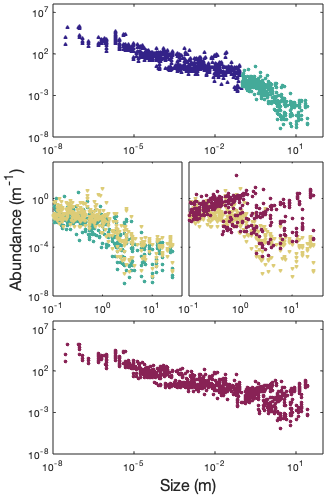


% c. 1500 samples across the full spectrum (1k laminar, 500 turbulent),
% can reroll if desired, or uncomment lines 15-19 in the script to plot the
% full dataset

plot_Fig1panel

#### Confirm the location of the structural break

Bootstrapped structural breakpoints and a percentile-based CI. Load pre-computed bootstrap vector (instant) or uncomment code (estimated runtime 5-20 mins). Requires the optimisation toolbox. The function uses code adapted from John D'Errico.

fprintf(' Structural break ')

 Structural break 


load('structbreakBootstraps.mat')

% or uncomment the lines below to run the code:

% numboot = 5000; % choose how many bootstraps to do
%
% structbreak =zeros(numboot,1);
% for i=1:numboot
% fullspect = generateSubsampledData(scalingdata,[-8,9/50,1.5],370,0,0); %
% structbreak(i) = bootstrapStructuralBreak(fullspect);
% end

meanbreak = mean(structbreak); %  mean
CIbreak = prctile(structbreak, [2.5,97.5]); % 95% CI (percentile)

fprintf(['The struct break is at %.2f m,\n with 95%% CI' ...
    ' of (%.2f, %.2f)'], meanbreak, CIbreak(1), CIbreak(2))

The struct break is at 0.08 m,
 with 95% CI of (0.06, 0.10)

#### Fit linear models to confirm the residuals are behaving appropriately

Before bootstrapping, make sure the assumption that we can log-transform and fit the linear model is appropriate, i.e. residuals are approximately normal.

% the following calls a script which creates a random subsample of each
% data type, and then plots the residuals of a linear model (fit with
% matlab's fitlm). Colours match the manuscript. This creates the residuals
% plots in Fig S1 and S2

% for reproducibility, comment out for new rolls
rng(92)

fprintf(' Residuals (of a representative subsample) of full dataset \n \n')

 Residuals (of a representative subsample) of full dataset 
 


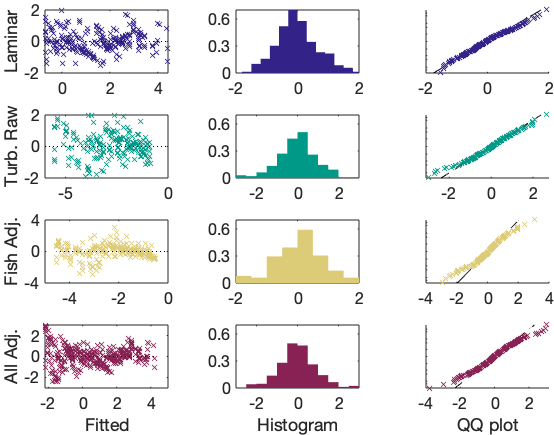

% first the full dataset
plot_residuals_FigS1_alldata


fprintf(' Residuals (of a representative subsample) of manually curated dataset \n \n')

 Residuals (of a representative subsample) of manually curated dataset 
 


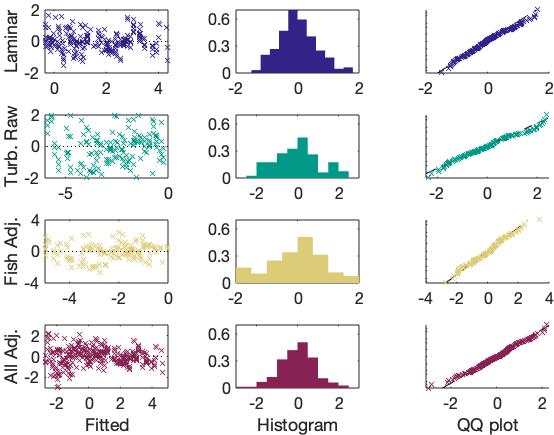

% then the manually curated dataset
plot_residuals_FigS2_manualdata

#### Bootstrapped alpha estimates

Residuals look generally ok, so bootstrap the slope values (alpha estimates). The function fitLM_subsampling.m uses MATLAB's backslash operator A\b for speed. Load pre-computed bootstraps (instant) or uncomment and run the raw code (est. runtime 25-40 minutes).

#### Subsample sizes *m=3*n^0.5:*

The coefficient may be 2 or 3; here we use 3.

**Full dataset: **Laminar: m=284    Turbulent: m=236    Full size range (turbulence adjusted): m=370

**Manually curated data: **Laminar: m=108    Turbulent: m=61    Full size range (turbulence adjusted): m=124

load('alphaEstBootstraps.mat') % 10k bootstrapped values for each alpha estimate

% if you want to run the bootstraps yourself, uncomment the lines below. Calls
% an empirical bootstrap function "bootstrapAlpha.m"

% numboot = 10000; % set how many times to resample.
% 
% % Full data tables
% lamAlphaEst = bootstrapAlpha(numboot, laminartable, binsLam, 284, 0);
% turbAlphaEst = bootstrapAlpha(numboot, turbulenttable, binsTurb, 236, 0);
% fadjAlphaEst = bootstrapAlpha(numboot, fishingadj, binsTurb, 236, 0);
% tadjAlphaEst = bootstrapAlpha(numboot, turbulenttable, binsTurb, 236, 1);
% fullAlphaEst = bootstrapAlpha(numboot, scalingdata, binsAll, 370, 1);
% 
% % Manually curated data only
% lamAlphaEstman = bootstrapAlpha(numboot, laminartableman, binsLam, 108, 0);
% turbAlphaEstman = bootstrapAlpha(numboot, turbulenttableman, binsTurb, 61, 0);
% fadjAlphaEstman = bootstrapAlpha(numboot, fishingadjman, binsTurb, 61, 0);
% tadjAlphaEstman = bootstrapAlpha(numboot, turbulenttableman, binsTurb, 61, 1);
% fullAlphaEstman = bootstrapAlpha(numboot, scalingdataman, binsAll, 124, 1);

Next confirm the bootstraps are well-behaved (histograms are as plotted in Fig S3). Create a results table with the means and 95% CIs (percentile), which is the empirical component of Table 1 in the manuscript.

fprintf('  Bootstrap histograms, estimates and CIs \n')

  Bootstrap histograms, estimates and CIs 


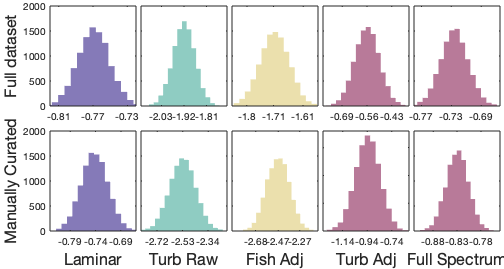


% Plot the bootstrapped results
plot_bootstrapHistograms


% Create results table with the bootstrapped outputs

ModelType = {'Laminar', 'Turbulent', 'Turbulent Fishing Adj.', 'Turbulence Adj.', 'All data'}';

% bootstrapped estimate, all data
alphaEstAllData = [mean(lamAlphaEst), mean(turbAlphaEst), mean(fadjAlphaEst), ...
    mean(tadjAlphaEst), mean(fullAlphaEst)]';
% percentile CIs, all data
CIsAlphaAllData = [prctile(lamAlphaEst, [2.5, 97.5]); prctile(turbAlphaEst, [2.5, 97.5]); ...
    prctile(fadjAlphaEst, [2.5, 97.5]); prctile(tadjAlphaEst, [2.5, 97.5]); prctile(fullAlphaEst, [2.5, 97.5])];

% bootstrapped estimate, manually curated data
alphaEstManData = [mean(lamAlphaEstman), mean(turbAlphaEstman), mean(fadjAlphaEstman), ...
    mean(tadjAlphaEstman), mean(fullAlphaEstman)]';
% percentile CI, manually curated data
CIsAlphaManData = [prctile(lamAlphaEstman, [2.5, 97.5]); prctile(turbAlphaEstman, [2.5, 97.5]); ...
    prctile(fadjAlphaEstman, [2.5, 97.5]); prctile(tadjAlphaEstman, [2.5, 97.5]); prctile(fullAlphaEstman, [2.5, 97.5])];

fprintf(['Table of alpha estimates and CIs (Table 1 in manuscript, empirical data)\n' ...
    'tag "All" denotes full dataset, "Man" denotes manually curated data'])

Table of alpha estimates and CIs (Table 1 in manuscript, empirical data)
tag "All" denotes full dataset, "Man" denotes manually curated data

% aggregate and print results table
resultsTable = table(ModelType, alphaEstAllData, CIsAlphaAllData, alphaEstManData, CIsAlphaManData)

resultsTable = 5×5 table
            ModelType             alphaEstAllData      CIsAlphaAllData       alphaEstManData      CIsAlphaManData   
    __________________________    _______________    ____________________    _______________    ____________________

    {'Laminar'               }        -0.7692        -0.80542    -0.73306       -0.74192        -0.79424    -0.68974
    {'Turbulent'             }        -1.9205         -2.0283     -1.8148        -2.5306         -2.7211     -2.3417
    {'Turbulent Fishing Adj.'}        -1.7065         -1.8043     -1.6127        -2.4717         -2.6779     -2.2684
    {'Turbulence Adj.'       }       -0.55927        -0.68647    -0.43348       -0.93712         -1.1367    -0.74135
    {'All data'              }       -0.72596        -0.76221     -0.6896       -0.82956        -0.875

#### See representative linear model fits

Look at some subsample plots and linear model statistical summaries. One model summary is set to display, the rest have output suppressed, add remove semicolons to print/suppress output.

fprintf(' Representative subsample linear regression fits \n')

 Representative subsample linear regression fits 


fprintf('gives a visual about what the estimates in Table 1 were being fit on\n')

gives a visual about what the estimates in Table 1 were being fit on


fprintf('each run will generate new subsamples\n')

each run will generate new subsamples


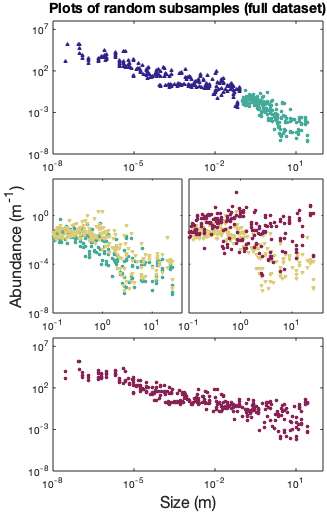

% reroll as desired, each roll will generate new datasets

% Generate subsamples, log transform
lamRepSample = log10(generateSubsampledData(laminartable, binsLam, 284, 0, 0));
turbRepSample = log10(generateSubsampledData(turbulenttable, binsTurb, 236, 0, 0));
fadjRepSample = log10(generateSubsampledData(fishingadj, binsTurb, 236, 0, 0));
tadjRepSample = log10(generateSubsampledData(turbulenttable, binsTurb, 236, 1, 0));
fullRepSample = log10(generateSubsampledData(scalingdata, binsAll, 370, 1, 0));

% Take a look at some plots of the subsamples just generated
plot_representativeSubsamples


% Generate datasets (manually curated) and log transform
lamRepSampleman = log10(generateSubsampledData(laminartableman, binsLam, 108, 0, 0));
turbRepSampleman = log10(generateSubsampledData(turbulenttableman, binsTurb, 61, 0, 0));
fadjRepSampleman = log10(generateSubsampledData(fishingadjman, binsTurb, 61, 0, 0));
tadjRepSampleman = log10(generateSubsampledData(turbulenttableman, binsTurb, 61, 1, 0));
fullRepSampleman = log10(generateSubsampledData(scalingdataman, binsAll, 124, 1, 0));


% LINEAR MODEL FITS: full dataset; add/remove semicolons to print or suppress output.
linmdlLaminar = fitlm(lamRepSample(:, 1), lamRepSample(:, 2));
linmdlTurbRaw = fitlm(turbRepSample(:, 1), turbRepSample(:, 2));
linmdlFishAdjusted = fitlm(fadjRepSample(:, 1), fadjRepSample(:, 2));
linmdlTurbAdjusted = fitlm(tadjRepSample(:, 1), tadjRepSample(:, 2));
linmdlFullSpectAdjusted = fitlm(fullRepSample(:, 1), fullRepSample(:, 2)) % displaying

linmdlFullSpectAdjusted = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)     -1.1835    0.070323    -16.829     2.9955e-46
    x1             -0.70764    0.020343    -34.786    4.3161e-112


Number of observations: 330, Error degrees of freedom: 328
Root Mean Squared Error: 0.869
R-squared: 0.787,  Adjusted R-Squared: 0.786
F-statistic vs. constant model: 1.21e+03, p-value = 4.32e-112


% LINEAR MODELS FITS: Manually curated dataset; add/remove semicolons to print or suppress output.
linmdlLaminarManual = fitlm(lamRepSampleman(:, 1), lamRepSampleman(:, 2));
linmdlTurbRawManual = fitlm(turbRepSampleman(:, 1), turbRepSampleman(:, 2));
linmdlFishAdjustedManual = fitlm(fadjRepSampleman(:, 1), fadjRepSampleman(:, 2));
linmdlTurbAdjustedManual = fitlm(tadjRepSampleman(:, 1), tadjRepSampleman(:, 2));
linmdlFullSpectAdjustedManual = fitlm(fullRepSampleman(:, 1), fullRepSampleman(:, 2));


## Model 

Reroll as many times as desired. 

The ODE paramaters are in "modelEquilibria.m", the scaffolding around the model call is in "generateModelResults.m", and the bootstrapping function is "bootstrapModelAlpha.m".

There is a bootstrap step at line 187, which will take 20-30 seconds

fprintf(' Model results ')

 Model results 


% for reproducibility, comment out for new roll
rng(496)

% choose how many predator-prey pairs
npairs = 400;

% get results for the turbulent regime model (turbulence on, flag = 0)
[predLengths, rho, equilibria, efficiency] = generateModelResults(npairs, 0);

% get results for the case turbulence is 'switched off' (flag=1)
[predLengthsAdj, rhoAdj, equilibriaAdj, efficiencyAdj] = generateModelResults(npairs, 1);


% generate a decent size empirical data subsample to plot (standardise lengths to match model)
lamdata = generateSubsampledData(scalingdata, binsLam, 3000, 0, 0);
fisadjdata = generateSubsampledData(fishingadj, binsTurb, 1000, 0, 0);
LSS = [log10(lamdata(:, 1) / 10^(-7.5)); log10(fisadjdata(:, 1) / 10^(-7.5))];
LSA = [log10(lamdata(:, 2)); log10(fisadjdata(:, 2))];


totdataAdj = generateSubsampledData(scalingdata, binsAll, 4000, 1, 0);
LSSAdj = log10(totdataAdj(:, 1)/10^(-7.5));
LSAAdj = log10(totdataAdj(:, 2));

E1 = [min(efficiency), max(efficiency)];
E2 = [min(efficiencyAdj), max(efficiencyAdj)];
fprintf('the min/max trophic transfer efficiencies \n in the turbulent model are %4.4f, %8.3f\n', E1)

the min/max trophic transfer efficiencies 
 in the turbulent model are 0.0004,    0.274


fprintf('the min/max trophic transfer efficiencies \n in the adjusted model are %4.4f, %8.3f\n', E2)

the min/max trophic transfer efficiencies 
 in the adjusted model are 0.0163,    0.341



% Get the model parameter estimates (bootstrap on the same number of
% datapoints as the empirical data subsamples)
fprintf('be patient... running bootstrap (20 seconds)\n')

be patient... running bootstrap (20 seconds)


[alphaEstModelLam, alphaEstModelTurb, alphaEstModelAdj] = bootstrapModelAlpha(10000);

alphaCIModLam = prctile(alphaEstModelLam, [2.5, 50, 97.5]);
alphaCIModTurb = prctile(alphaEstModelTurb, [2.5, 50, 97.5]);
alphaCIModAdj = prctile(alphaEstModelAdj, [2.5, 50, 97.5]);

fprintf('Model alpha estimates and CIs (Table 1 model results)\n')

Model alpha estimates and CIs (Table 1 model results)


fprintf('bootstrapped mean and CI for the model in the laminar regime is \n %.3f, (%.3f, %.3f)\n', alphaCIModLam(2), alphaCIModLam(1), alphaCIModLam(3))

bootstrapped mean and CI for the model in the laminar regime is 
 -0.768, (-0.794, -0.741)


fprintf('bootstrapped mean and CI for the model in the turbulent regime is \n %.3f, (%.3f, %.3f)\n', alphaCIModTurb(2), alphaCIModTurb(1), alphaCIModTurb(3))

bootstrapped mean and CI for the model in the turbulent regime is 
 -2.099, (-2.177, -2.021)


fprintf('bootstrapped mean and CI for the full adjusted model is \n %.3f, (%.3f, %.3f)\n', alphaCIModAdj(2), alphaCIModAdj(1), alphaCIModAdj(3))

bootstrapped mean and CI for the full adjusted model is 
 -0.729, (-0.736, -0.721)


#### Plot figures (equilibria abundances)

Plot the results and check a linear model summary of the plotted model data. Recreates Fig. 3.

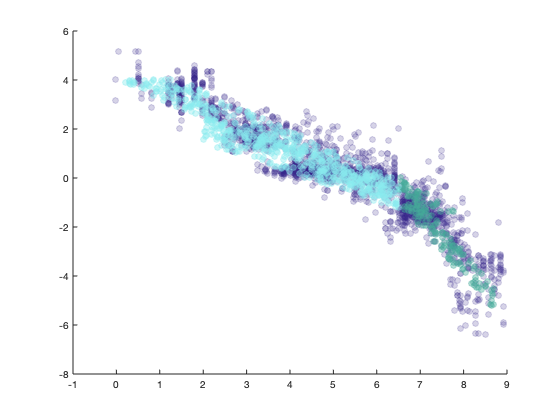

% create some RGB triplets
mutedteal = [68, 170, 153] ./ 255;
mutedwine = [136, 34, 85] ./ 255;
mutedcyan = [136, 234, 238] ./ 255;
mutedindigo = [51, 34, 136] ./ 255;

% transforms model output, takes organisms >= 0.1 m and fits regression
lengths = [predLengths; predLengths .* rho];
abundances = 10.^[equilibria(:, 2); equilibria(:, 1)];

% get indices of turbulent/laminar regime organisms
idxTurb = lengths >= 0.1 / (10^(-7.5));
idxLam = lengths < 0.1 / (10^(-7.5));

figure
hold on
%superimpose the model results and do some formatting
scatter3 = scatter(LSS, LSA, 'o', 'MarkerEdgeColor', mutedindigo, 'MarkerFaceColor', mutedindigo);
scatter3.MarkerFaceAlpha = .2;
scatter3.MarkerEdgeAlpha = .2;

scatter1 = scatter(log10(lengths(idxTurb)), log10(abundances(idxTurb)), 'o', 'MarkerEdgeColor', mutedteal, 'MarkerFaceColor', mutedteal);
scatter1.MarkerFaceAlpha = .4;
scatter1.MarkerEdgeAlpha = .4;

scatter2 = scatter(log10(lengths(idxLam)), log10(abundances(idxLam)), 'o', 'MarkerEdgeColor', mutedcyan, 'MarkerFaceColor', mutedcyan);
scatter2.MarkerFaceAlpha = .4;
scatter2.MarkerEdgeAlpha = .4;
hold off



% Fit linear model to turbulent data
fprintf('model summary of regression fit on ~100 pp pairs, turbulent data only')

model summary of regression fit on ~100 pp pairs, turbulent data only

modelRegressTurb = fitlm(log10(lengths(idxTurb)), log10(abundances(idxTurb)))

modelRegressTurb = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     13.742      0.42316    32.475    2.5106e-73
    x1             -2.1414     0.056936    -37.61    1.5052e-82


Number of observations: 166, Error degrees of freedom: 164
Root Mean Squared Error: 0.431
R-squared: 0.896,  Adjusted R-Squared: 0.895
F-statistic vs. constant model: 1.41e+03, p-value = 1.51e-82

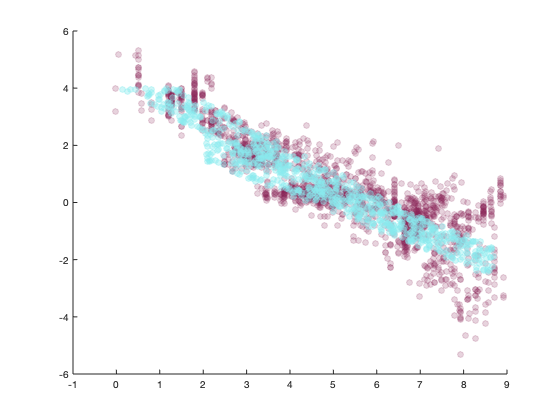



figure
hold on
%superimpose the model results and do some formatting
scatter3 = scatter(LSSAdj, LSAAdj, 'o', 'MarkerEdgeColor', mutedwine, 'MarkerFaceColor', mutedwine);
scatter3.MarkerFaceAlpha = .2;
scatter3.MarkerEdgeAlpha = .2;

scatter1 = scatter(log10(predLengthsAdj), equilibriaAdj(:, 2), 'o', 'MarkerEdgeColor', mutedcyan, 'MarkerFaceColor', mutedcyan);
scatter1.MarkerFaceAlpha = .4;
scatter1.MarkerEdgeAlpha = .4;

scatter2 = scatter(log10(predLengthsAdj .* rhoAdj), equilibriaAdj(:, 1), 'o', 'MarkerEdgeColor', mutedcyan, 'MarkerFaceColor', mutedcyan);
scatter2.MarkerFaceAlpha = .4;
scatter2.MarkerEdgeAlpha = .4;
hold off


% Fit linear model to adjusted/laminar data
% transforms model output and fits linear regression
lengthsAdj = [predLengthsAdj; predLengthsAdj .* rhoAdj];
abundancesAdj = 10.^[equilibriaAdj(:, 2); equilibriaAdj(:, 1)];
fullspectModelData = log10([lengthsAdj, abundancesAdj]);
fprintf('model summary of regression fit on 400 pp pairs, all adjusted data')

model summary of regression fit on 400 pp pairs, all adjusted data

modelRegressFullSpect = fitlm(fullspectModelData(:, 1), fullspectModelData(:, 2))

modelRegressFullSpect = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)      4.0616     0.036358     111.71      0   
    x1             -0.72685    0.0070601    -102.95      0   


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 0.417
R-squared: 0.93,  Adjusted R-Squared: 0.93
F-statistic vs. constant model: 1.06e+04, p-value = 0